# Find SC


%% import the data if already converted to ANA
dir= 'E:\PhD\Adamantane_data\data\Ada_PEPICO_hv350eV_ke260_0003\Ada_PEPICO_hv350eV_ke260_0003_ana';
raw_data = IO.import_raw(dir);
mdata = md_all();
data            = macro.filter(raw_data, mdata); %define the multiplicity of events
data_corrected = macro.correct(data, mdata);

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


data_converted = macro.convert(data_corrected, mdata);

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2
Log: Background signal created for det2 on the signal(s) TOF,


## Event statistics from all data

e_R_range = [0; 19.0];
e_TRG.C1= macro.filter.write_coincidence_condition(1, 'det1'); % electron trigger
e_TRG.type	        = 'continuous';
e_TRG.data_pointer	= 'h.det1.R';
e_TRG.translate_condition = 'AND';
e_TRG.value		= e_R_range;

RND_TRG= macro.filter.write_coincidence_condition(0, 'det1'); % rnd trigger

[e_filter_et, ~]	= macro.filter.conditions_2_filter(data_converted,e_TRG);
data_stats.N_e = sum(e_filter_et);
[e_filter_rt, ~]	= macro.filter.conditions_2_filter(data_converted, RND_TRG);
data_stats.N_RND = sum(e_filter_rt);
%%% the scaling factor%%%
% SC = data_stats.N_e / data_stats.N_RND;
SC = 0.3974;
% [data_stats] =get_data_stats(data_converted);
% SC = data_stats.SC;
% TP_0 =data_stats.TP_0;

## Define etAI and rtAI

hit_filter_et = filter.events_2_hits(e_filter_et, data_converted.e.raw, [2, length(data_converted.h.det2.TOF)],...
    e_TRG, data_converted);
et_m2q= data_converted.h.det2.m2q(hit_filter_et.det2.filt); 

hit_filter_rt = filter.events_2_hits(e_filter_rt, data_converted.e.raw, [2, length(data_converted.h.det2.TOF)],...
    RND_TRG, data_converted);
rt_m2q= data_converted.h.det2.m2q(hit_filter_rt.det2.filt);

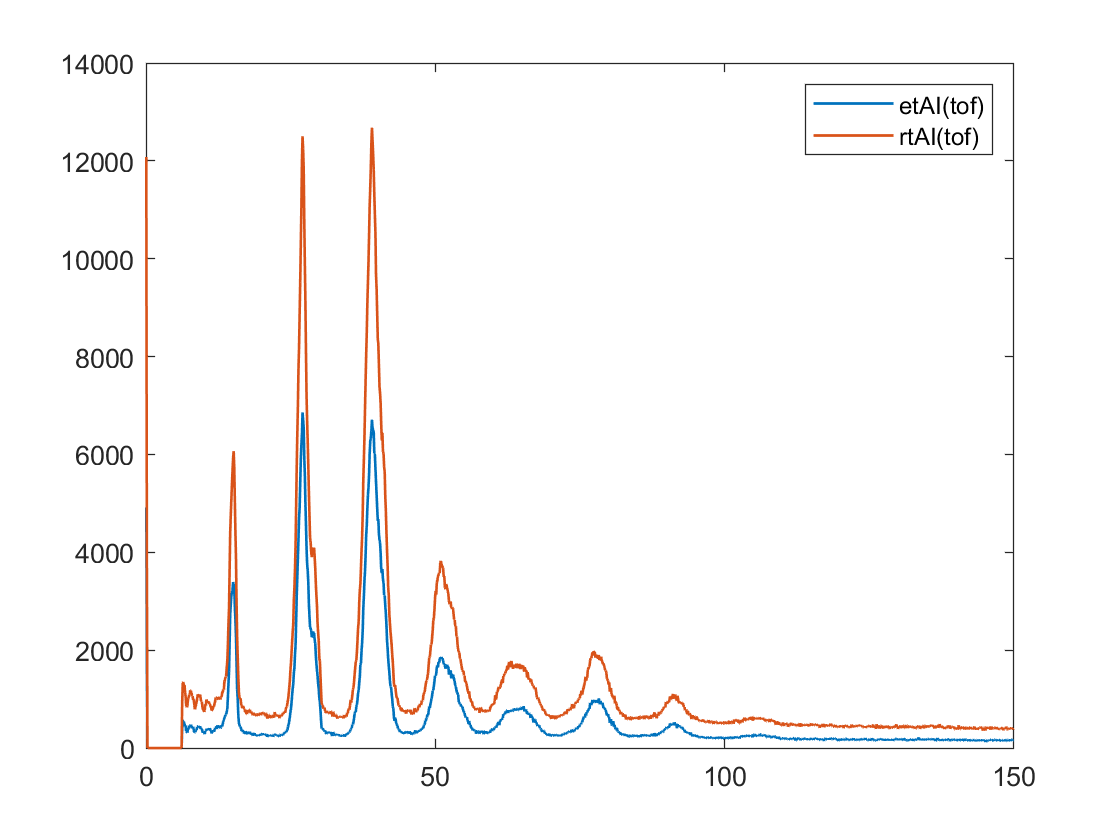

%% make histogram

Binsize = 0.1; Binedges = 0: Binsize: 150;
Bincenters = Binedges(1:end-1) + diff(Binedges) / 2;
et_m2q_hist= histcounts(et_m2q, Binedges);%,'Normalization','probability');
rt_m2q_hist= histcounts(rt_m2q, Binedges);%,'Normalization','probability');
figure
plot(Bincenters, et_m2q_hist,'LineWidth',1,'DisplayName','etAI(tof)')
hold on
plot(Bincenters, rt_m2q_hist,'LineWidth',1,'DisplayName','rtAI(tof)' )
legend

## Filter Ion TOF

figure
Tet_m2q = et_m2q_hist - SC.* rt_m2q_hist;
% Tet_tof = max(Tet_tof,0);
Tet_m2q_error = sqrt(et_m2q_hist + (SC.^2).* rt_m2q_hist)

Tet_m2q_error =    82.6041   45.9337         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


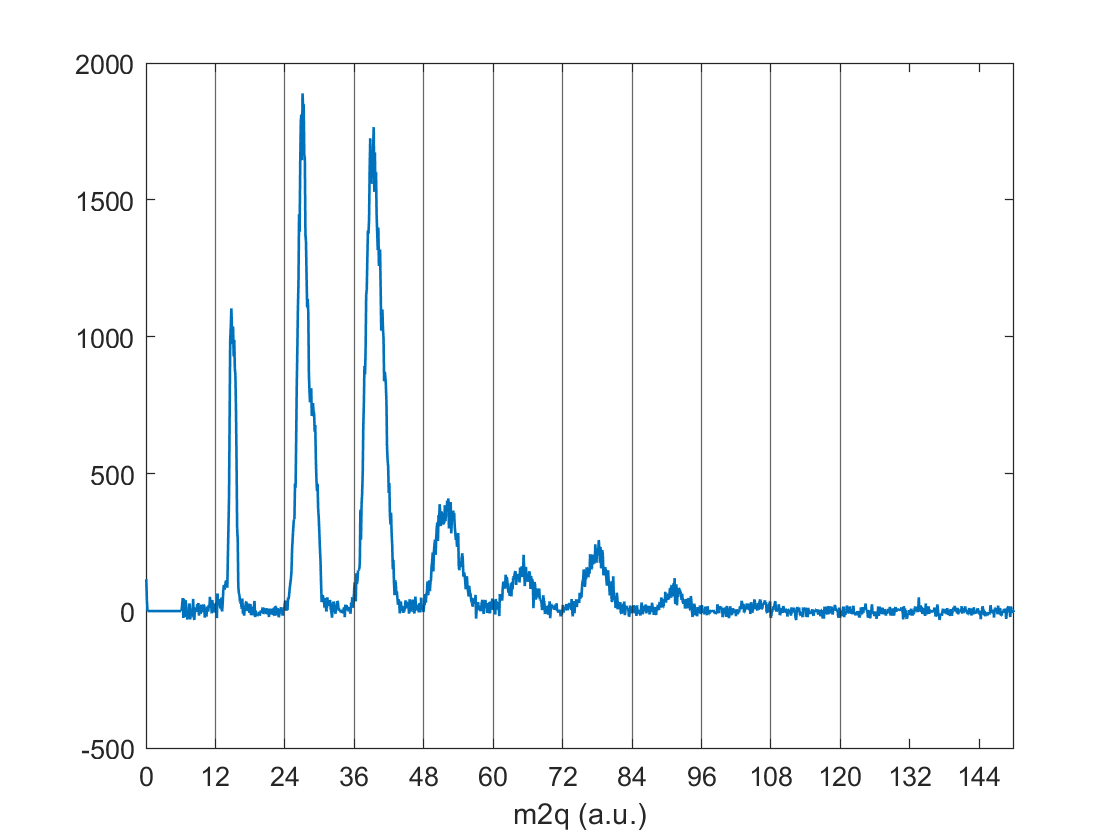

plot(Bincenters, Tet_m2q ,'LineWidth',1,'DisplayName','TetAI(tof)')
xlabel('m2q (a.u.)')
for kk =1:10
    xline(12*(kk));
end
xticks(0:12:150)

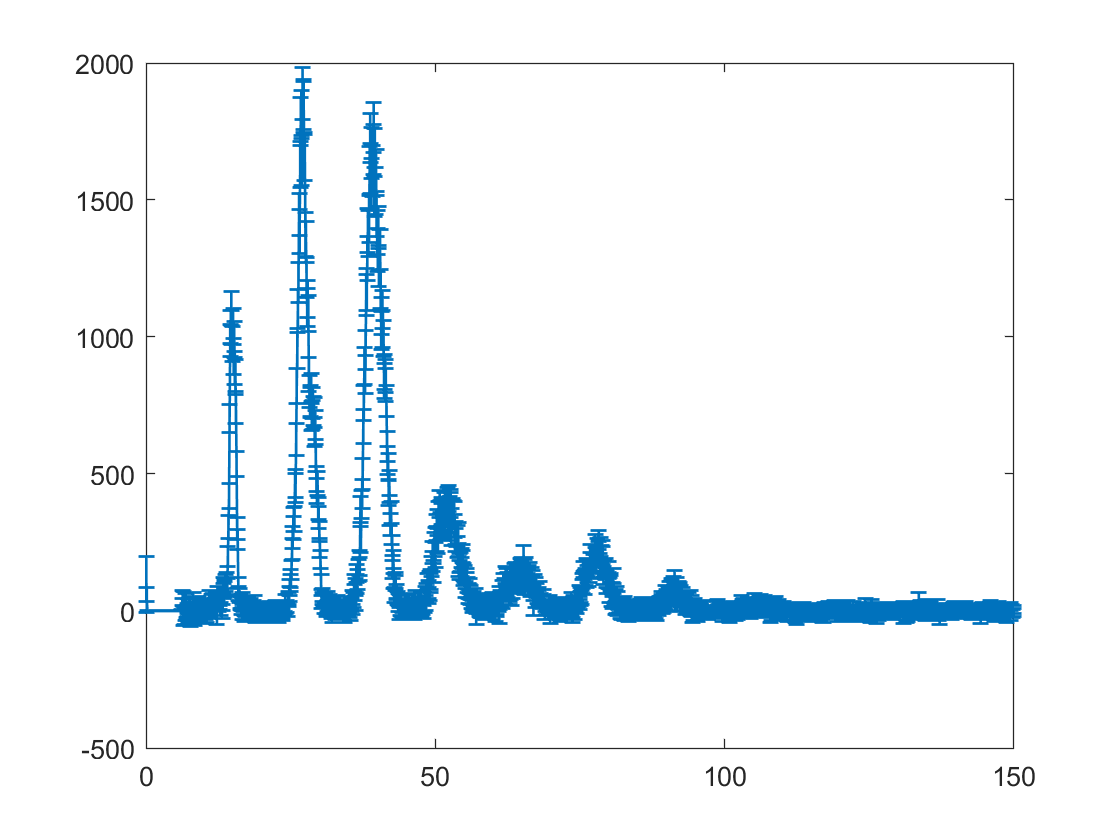

figure
errorbar(Bincenters,Tet_m2q ,Tet_m2q_error, 'LineWidth',1,'DisplayName','TetAI(tof)')